# Initialization Script

clear, clc, close all

% Run FG
% dos('runfg172p.bat &');

### Task Configuration

%- ADS -%
Lvl  = "Level_1";

%- Axis Selection -%
axis = "Pitch";

%- Aggressiveness -%
task = "Non-aggressive";

Ts = 1/30;               % Sample rate
TendXc = 60;             % Score time
Tpause = 5;              % wait time to activate signal
Tend = TendXc + Tpause;

### **Initial Conditions ** 


% Long.                 |     Lat.
  u0   = 176;                 v0   = 0;  
  w0   = 0;                   p0   = 0;
  q0   = 0;                   r0   = 0;
  tht0 = -1.87*pi/180;        phi0 = 0;
  h0   = 5000;                psi0 = 0;  

% IC vector for state-space block
x0 = [u0, w0, q0, tht0, h0, v0, p0, r0, phi0, psi0]';

% initial long and lat (near Stillwater)
l_mu0 = [36.161201477051; -97.08570098877];    


### Flight Dynamics Formulation

% Variable Stability/Control Derivatives
switch Lvl
    case "Level_1"
        Mq = -3.5
        Yv = -4
    case "Level_2"
        Mq = -1.4
        Yv = -1.85
    case "Level_3"
        Mq = -0.6
        Yv = -0.75
end

Mq = -3.5000

Yv = -4


Xu  = -0.01;     % 1/s
Zw  = -1;        % 1/s
% Mq  = -3;        % 1/s
% Yv  = -0.02;     % 1/s
Lp  = -5;        % 1/s
Nr  = -5;        % 1/s
ZdC = -7;        % ft/s^2
MdB = -0.7;      % 1/s^2
LdA = 2;         % 1/s^2
Ndp = 3;         % 1/s^2
g   = 32.17;     % ft/s^2

% Shorthand for trig functions
s = @(angle) sin(angle);    c = @(angle) cos(angle);
t = @(angle) tan(angle);    S = @(angle) sec(angle);


% State-space formulation from Beard & McLain
Along = [ Xu        0        0   -g*c(tht0)              0;
          0         Zw       u0   0                      0;
          0         0        Mq   0                      0;
          0         0        1    0                      0;
          s(tht0)  -c(tht0)  0    u0*c(tht0)+w0*s(tht0)  0; ];
    

Alat = [ Yv  0  -u0               g*c(tht0)*c(phi0)                       0;
         0   Lp  0                0                                       0;
         0   0   Nr               0                                       0;
         0   1   c(phi0)*t(tht0)  q0*c(phi0)*t(tht0)-r0*s(phi0)*t(tht0)   0;
         0   0   c(phi0)*S(tht0)  p0*c(phi0)*S(tht0)-r0*s(phi0)*S(tht0)   0; ];

% Zero cross-coupling matrix
Acc = zeros(size(Alat));    

% Concatenate
A = [Along Acc ;
     Acc   Alat;];

B = [ 0    0    0    0;
      0    ZdC  0    0;
      MdB  0    0    0;
      0    0    0    0;
      0    0    0    0;
      0    0    0    0;
      0    0    LdA  0;
      0    0    0    Ndp;
      0    0    0    0;
      0    0    0    0;];

C = eye(10);
D = zeros(length(C), length(B(1,:)));


### Tracking Task

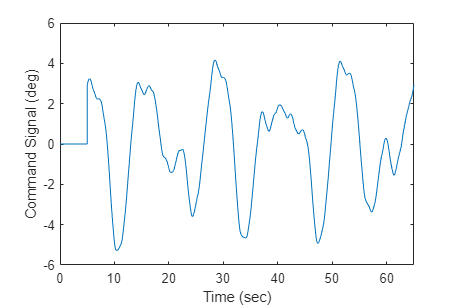

% Load MTE signal data to workspace 
switch task
    case 'Non-aggressive'
        [~,~, Pitch, Roll] = SOSInput_mod(Tpause, Ts, TendXc);
    case 'Aggressive'
        [Pitch, Roll, ~,~] = SOSInput_mod(Tpause, Ts, TendXc);
end

switch axis
    case 'Pitch'
        Roll(:,2) = zeros([length(Roll), 1]);
    case 'Roll'
        Pitch(:,2) = zeros([length(Pitch), 1]);
    case 'Multi'
        % No change
end


figure("Name",'Sum-of-Sines Command Input')
plot(Pitch(:,1), Pitch(:, 2))
set(gcf, 'Position', [10, 10, 600, 400])
ylim([-6, 6])
xlim([0, 65])
% title('Sum-of-Sines Command Input')
ylabel('Command Signal (deg)')
xlabel('Time (sec)')